# In the name of allah

# Signals and Systems 

# Project Phaze 1

professor khalaj

Ali sadeghian 400101464

mohammadparsadini 400101204

https://github.com/BlackRanger4/Sys_phaze2.git

clc
clear all
close all

# Part 1

In this part, we are trying to find the image of the professor among the professors, for this, we used function normxcorr2 

and output the highest correlation value as the image of the professor.

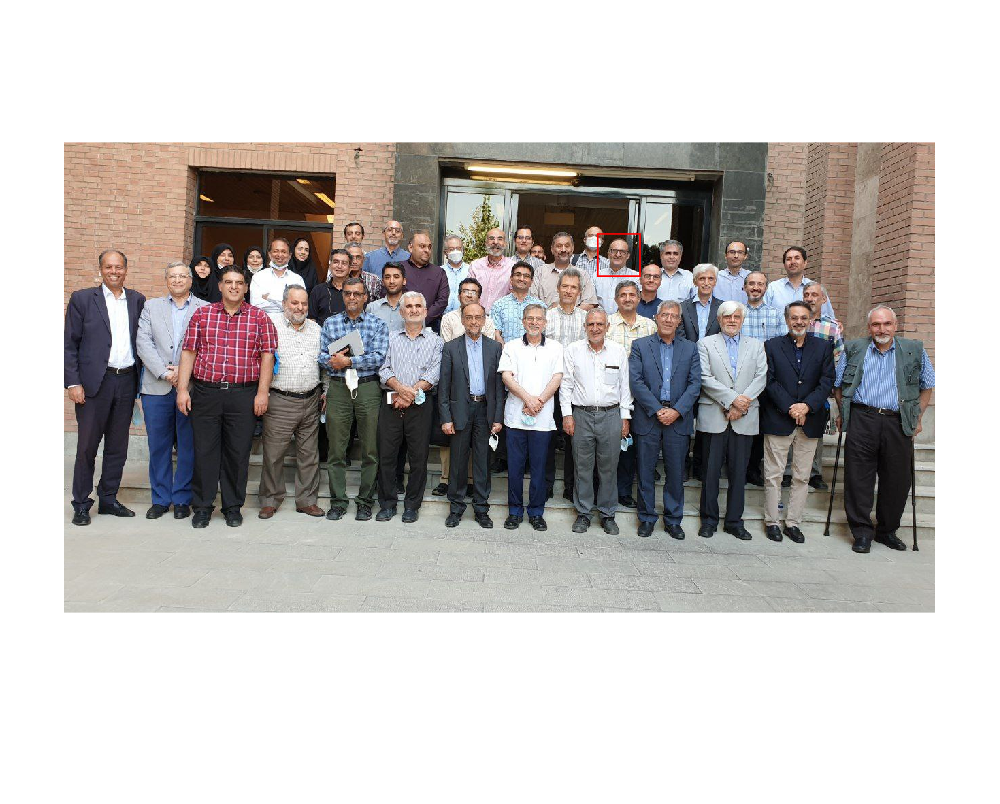

% Read the images
img = (imread('background.jpg'));
imgp =imread('template.jpg');
img1 = im2gray(img);
img2 = im2gray(imgp);

% Find the second image in the first image
c = normxcorr2(img2,img1);

% Find the peak correlation
[max_c, imax] = max(abs(c(:)));
[ypeak, xpeak] = ind2sub(size(c),imax(1));

% Calculate offset
corr_offset = [(xpeak-size(img2,2)) (ypeak-size(img2,1))];

% Draw a rectangle around the second image
figure; 
imshow(img);
rectangle('Position',[corr_offset(1) corr_offset(2) size(img2,2) size(img2,1)],'EdgeColor','r','LineWidth',1);

% Save the resulting image
%imwrite(getframe(gca).cdata,'TemplateMatching.jpg');

# Part 2

In this part, first we recognize the different notes, we also recognize the dot and diaz bmel, we recognize the 

carrier lines, we identify the position of the notes in relation to the carrier lines, and we recognize the correct 

octave and note. Finally, we create the music using the functions given by the designer.

## Twinkle, Twinkle, Little Star

finding notes

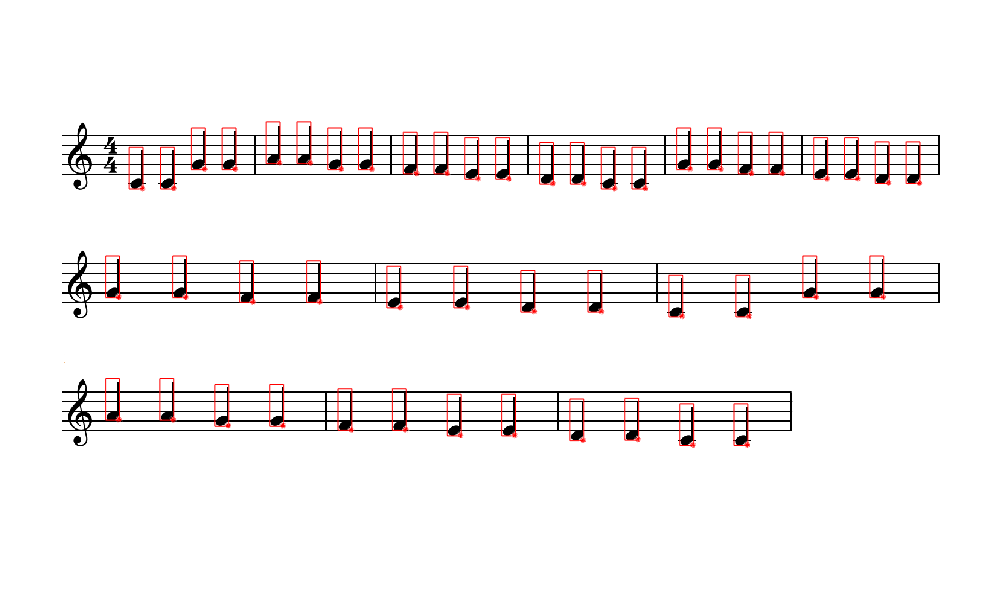

% Read the first image
image1 = imread("Twinkle.png"); 
[H , W ,~] = size(image1); 

% Read the second image
image2 = imread("quarter.PNG");   
[h , w ,~] = size(image2);

% Convert the images to grayscale
gray_image1 = rgb2gray(image1);
gray_image2 = rgb2gray(image2);

% Find the size of the second image
[height, width] = size(gray_image2);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image2, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

points = output_points;

% Divide the vertical axis into three parts
part1 = points(points(:,1) <= 185,:);
part2 = points(points(:,1) > 185 & points(:,1) <= 370,:);
part3 = points(points(:,1) > 370,:);

% Sort each part based on the horizontal component
part1 = sortrows(part1,2);
part2 = sortrows(part2,2);
part3 = sortrows(part3,2);

% Combine the sorted parts into a single matrix
sorted_points = [part1,; part2; part3];

sorted_points(end,:) = [];
rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding carrier lines

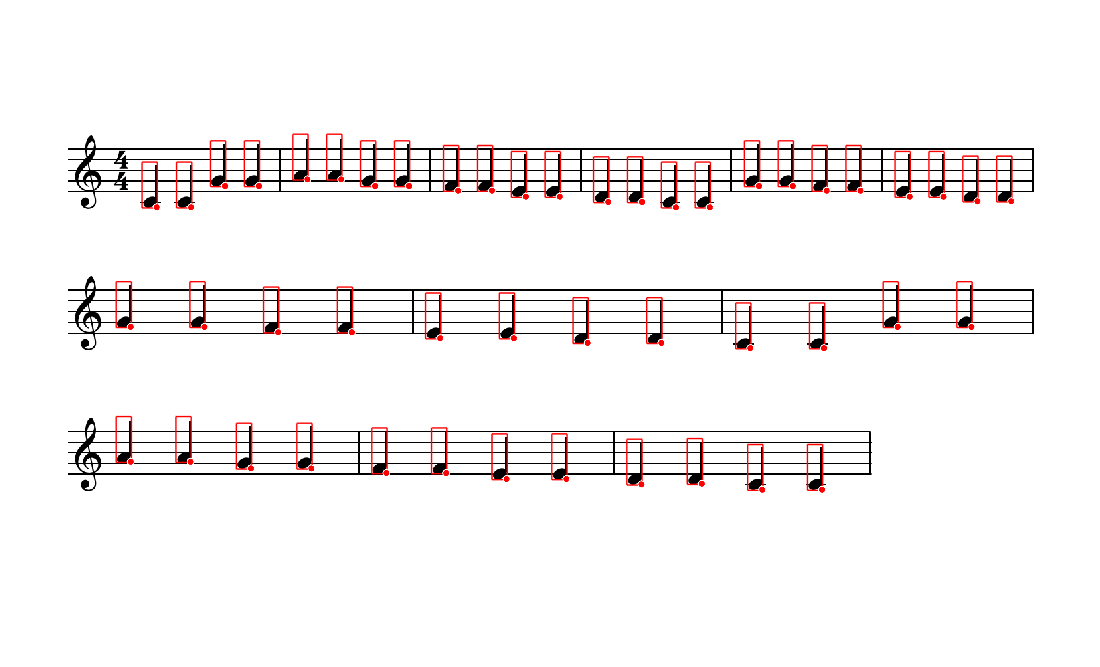

% Read the image
img = imread("Twinkle.png");

% Convert the image to grayscale
gray_img = rgb2gray(img);

% Threshold the image to create a binary image
bw_img = gray_img < 128;

% Compute the sum of each row of the binary image
row_sums = sum(bw_img,2);

% Find the rows whose sum exceeds a certain value and change their color in the main picture
threshold = 800;
rows_to_change = row_sums > threshold;
rows_to_change1 =find(rows_to_change);


% Define the maximum distance between adjacent elements
max_distance = 2;

% Compute the difference between adjacent elements
d = diff(rows_to_change1);

% Find the indices of the elements that are close to each other
idx = find(abs(d) <= max_distance);

% Remove the elements that are close to each other
rows_to_change1 = setdiff(rows_to_change1,rows_to_change1(idx+1));

R = ones([size(rows_to_change1,1) W])*255;
G = ones([size(rows_to_change1,1) W])*255;
B = ones([size(rows_to_change1,1) W])*255;
Show =ones([size(rows_to_change1,1) W 3]); 
Show(:,:,1) =  R ;
Show(:,:,1) =  G ;
Show(:,:,1) =  B ;

img(rows_to_change1,:,:) = Show;
% Display the resulting image
imshow(img);

finding relative coordinates , create and play music  

a = zeros([size(sorted_points,1) 1]);
not_id  = zeros([size(sorted_points,1) 1]);
octave  = zeros([size(sorted_points,1) 1]);
dur = ones([size(sorted_points,1) 1]) * 4 ;
for i=1:size(sorted_points,1)
    a(i) = Mat33(sorted_points(i,1),rows_to_change1);
    [not_id(i), octave(i)] = Mat3(a(i),0);
end
music = round([not_id,octave,dur]);
fs1 = 8000;
 y = get_music(music, fs1);
sound(y, fs1)
%audiowrite("Twinkle_Twinkle_Little Star.wav",y,fs1);

## AveMaria

clc
clear all
close all

% Read the first image
image1 = imread("AveMaria.png");
[H , W ,~] = size(image1); 

% Read the second image
image2 = imread("quarter.PNG");
[h , w ,~] = size(image2);

% Read the third image
image3 = imread("half.PNG");
[h1 , w1 ,~] = size(image3);

% Read the forth image
image4 = imread("whole.PNG");
[h2 , w2 ,~] = size(image4);


% Convert the images to grayscale
gray_image1 = rgb2gray(image1);
gray_image2 = rgb2gray(image2);
gray_image3 = rgb2gray(image3);
gray_image4 = rgb2gray(image4);

## finding notes

finding  quarters

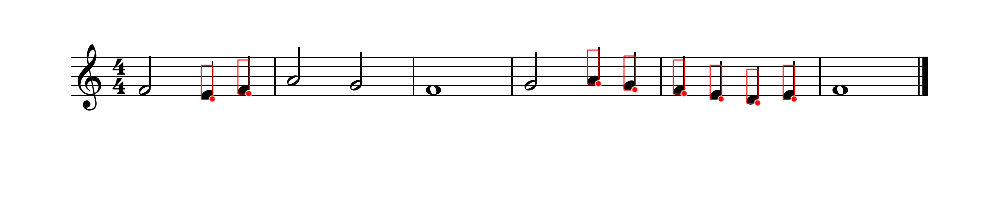

% Find the size of the second image
[height, width] = size(gray_image2);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image2, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [sorted_points , 4*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  halfs

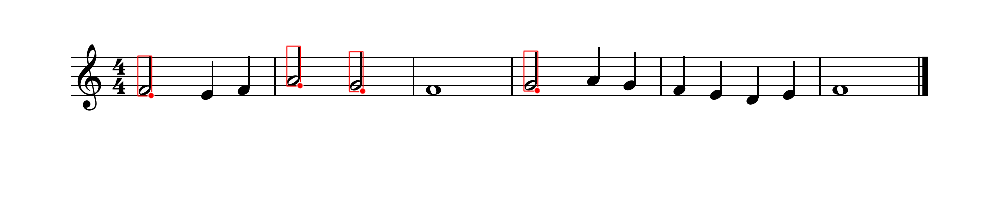

% Find the size of the second image
[height, width] = size(gray_image3);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image3, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.75;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding wholes

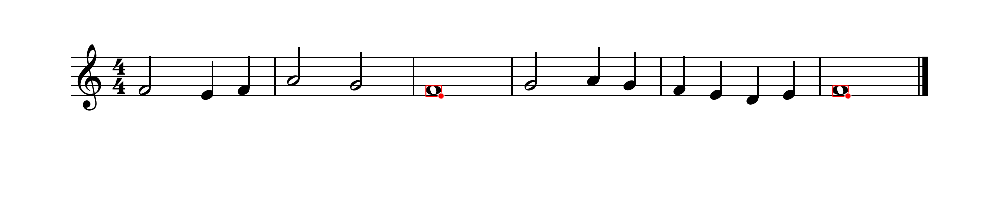

% Find the size of the second image
[height, width] = size(gray_image4);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image4, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end
% sort
sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 2*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

% sort all points
Final_sorted_points = sortrows(Final_sorted_points,2);

finding carrier lines

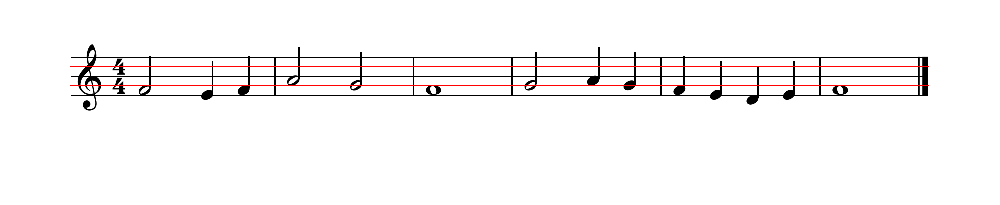

% Read the image
img = imread("AveMaria.png");

% Convert the image to grayscale
gray_img = rgb2gray(img);

% Threshold the image to create a binary image
bw_img = gray_img < 128;

% Compute the sum of each row of the binary image
row_sums = sum(bw_img,2);

% Find the rows whose sum exceeds a certain value and change their color in the main picture
threshold = 800;
rows_to_change = row_sums > threshold;
rows_to_change1 =find(rows_to_change);


% Define the maximum distance between adjacent elements
max_distance = 2;

% Compute the difference between adjacent elements
d = diff(rows_to_change1);

% Find the indices of the elements that are close to each other
idx = find(abs(d) <= max_distance);

% Remove the elements that are close to each other
rows_to_change1 = setdiff(rows_to_change1,rows_to_change1(idx+1));

R = ones([size(rows_to_change1,1) W])*255;
G = ones([size(rows_to_change1,1) W])*255;
B = ones([size(rows_to_change1,1) W])*255;
Show =ones([size(rows_to_change1,1) W 3]); 
Show(:,:,1) =  R ;
Show(:,:,1) =  G ;
Show(:,:,1) =  B ;

img(rows_to_change1,:,:) = Show;
% Display the resulting image
imshow(img);

finding relative coordinates , create and play music 

a = zeros([size(Final_sorted_points,1) 1]);
not_id  = zeros([size(Final_sorted_points,1) 1]);
octave  = zeros([size(Final_sorted_points,1) 1]);
dur = Final_sorted_points(:,3) ;
for i=1:size(Final_sorted_points,1)
    a(i) = Mat33(Final_sorted_points(i,1),rows_to_change1);
    [not_id(i), octave(i)] = Mat3(a(i),0);
end
music = round([not_id,octave,dur]);
fs1 = 4100;
 y = get_music(music, fs1);
sound(y, fs1)
%audiowrite("AveMaria.wav",y,fs1);

## Polyushka-polye

clc
clear all
close all

% Read the first image
image1 = imread("Polye.png");
[H , W ,~] = size(image1); 

% Read the second image
image2 = imread("quarter.PNG");
[h , w ,~] = size(image2);

% Read the third image
image3 = imread("half.PNG");
[h1 , w1 ,~] = size(image3);

% Read the forth image
image4 = imread("half2.PNG");
[h2 , w2 ,~] = size(image4);

% Read the fifth image
image5 = imread("whole.PNG");
[h3 , w3 ,~] = size(image5);

% Read the sixth image
image6 = imread("flat.PNG");
[h4 , w5 ,~] = size(image6);

% Read the seventh image
image7 = imread("sharp.PNG");
[h6 , w7 ,~] = size(image7);

% Convert the images to grayscale
gray_image1 = rgb2gray(image1);
gray_image2 = rgb2gray(image2);
gray_image3 = rgb2gray(image3);
gray_image4 = rgb2gray(image4);
gray_image5 = rgb2gray(image5);
gray_image6 = rgb2gray(image6);
gray_image7 = rgb2gray(image7);

finding  quarters

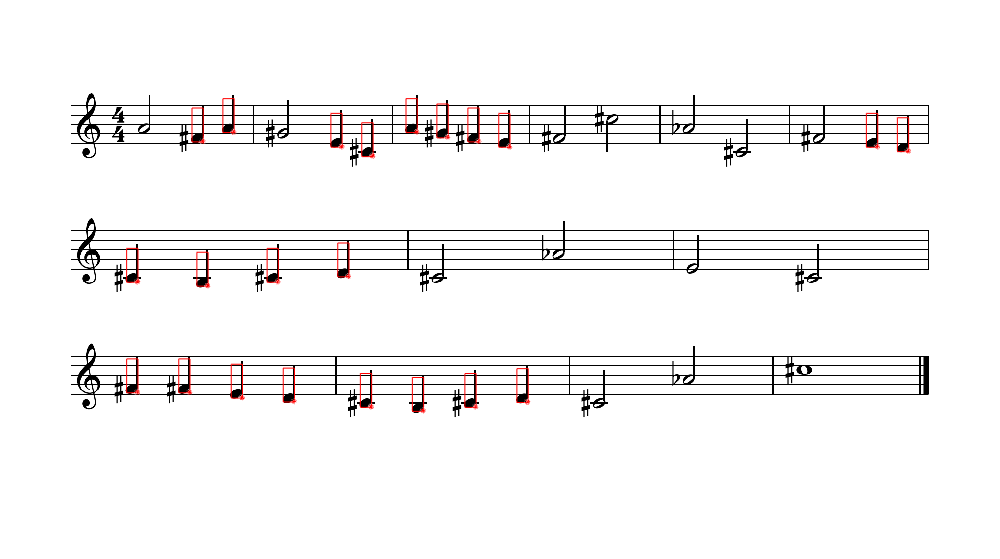

% Find the size of the second image
[height, width] = size(gray_image2);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image2, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.79;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
sorted_points(end,:) = [];
Final_sorted_points = [sorted_points , 4*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  halfs

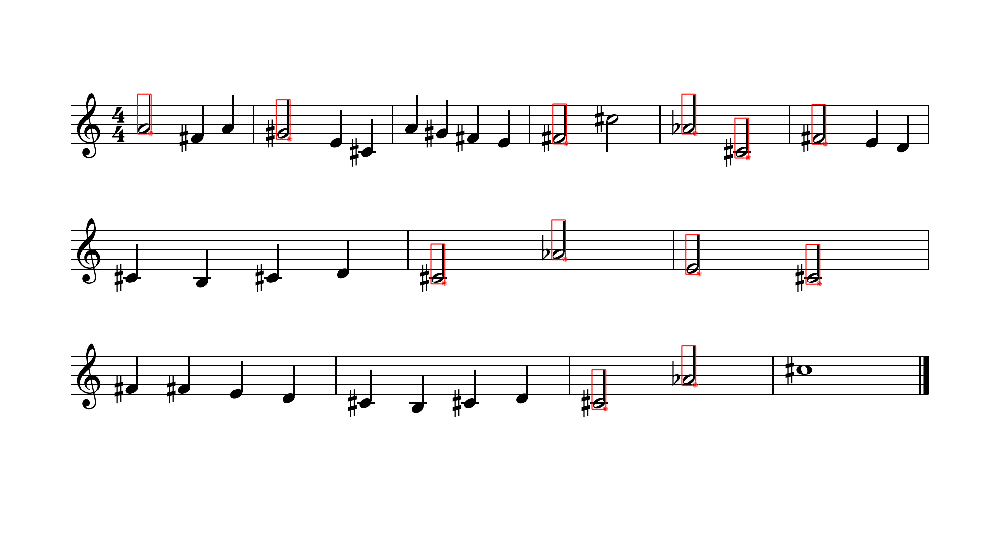

% Find the size of the second image
[height, width] = size(gray_image3);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image3, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.75;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  invert halfs

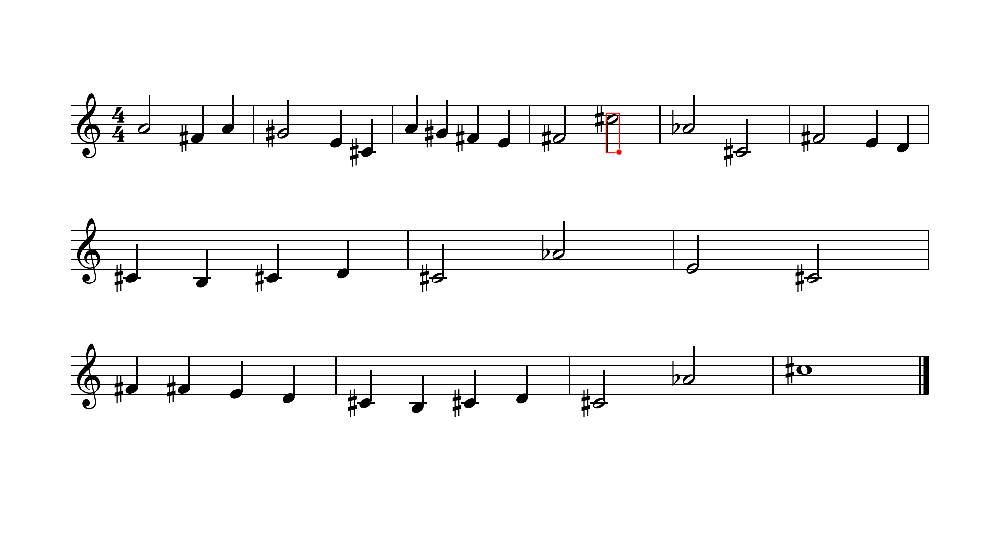

% Find the size of the second image
[height, width] = size(gray_image4);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image4, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.75;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3.2*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding wholes

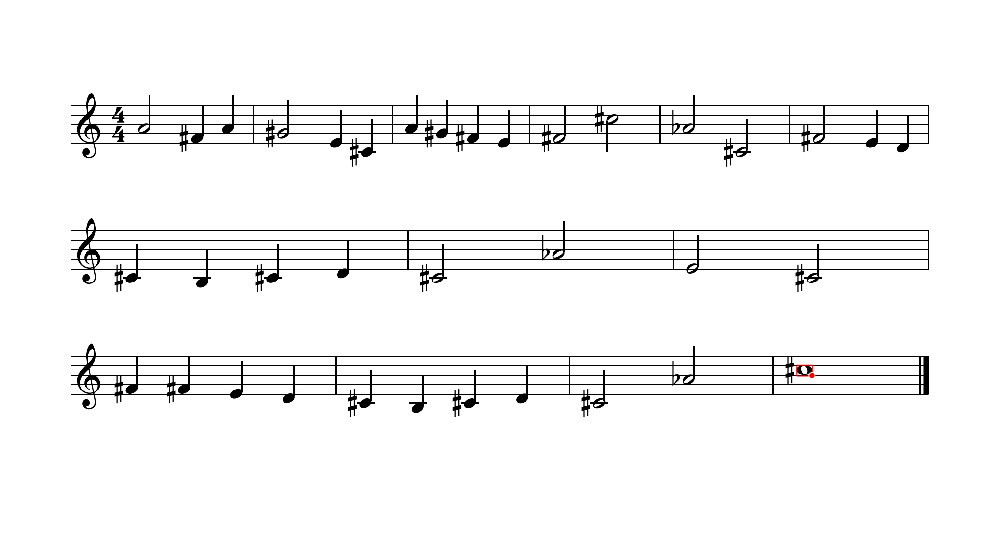

% Find the size of the second image
[height, width] = size(gray_image5);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image5, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end
% sort
sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 2*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

% Divide the vertical axis into three parts
part1 = Final_sorted_points(Final_sorted_points(:,1) <= 190,:);
part2 = Final_sorted_points(Final_sorted_points(:,1) > 190 & Final_sorted_points(:,1) <= 410,:);
part3 = Final_sorted_points(Final_sorted_points(:,1) > 410,:);

% Sort each part based on the horizontal component
part1 = sortrows(part1,2);
part2 = sortrows(part2,2);
part3 = sortrows(part3,2);

% Combine the sorted parts into a single matrix
Final_sorted_points = [part1,; part2; part3];

finding diese

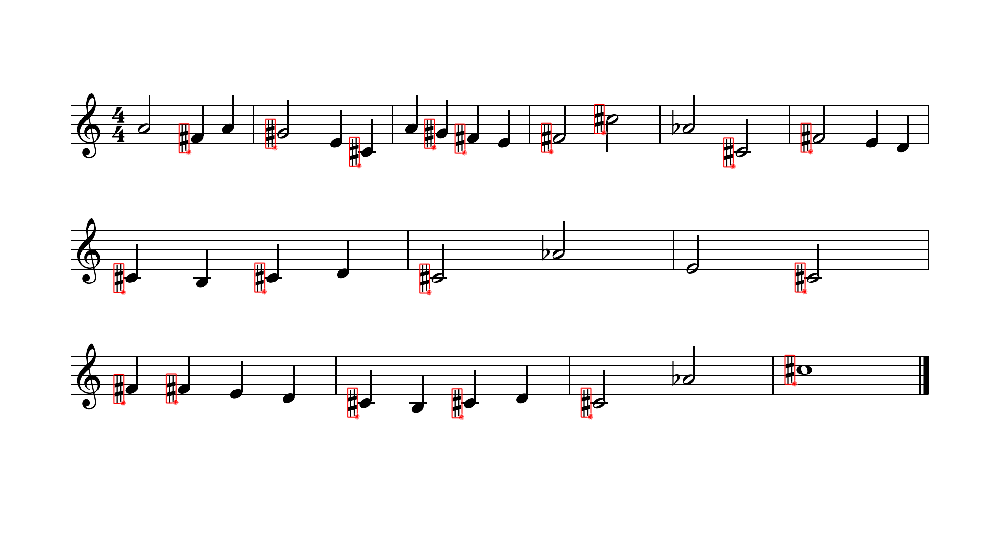

% Find the size of the second image
[height, width] = size(gray_image7);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image7, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end
% sort
sorted_points  = output_points;
Final_D_points = sorted_points;

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding bemol

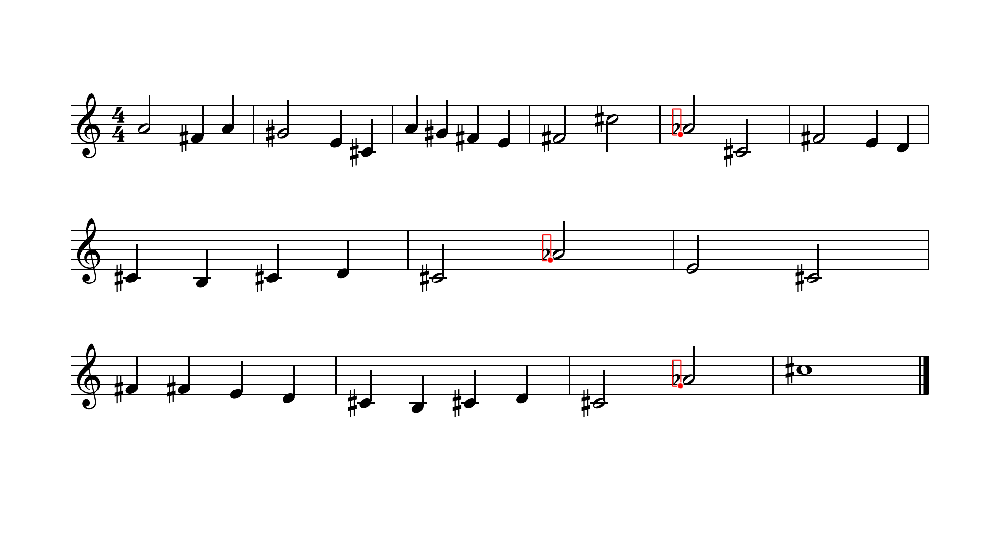

% Find the size of the second image
[height, width] = size(gray_image6);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image6, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end
% sort
sorted_points = output_points;
Final_B_points = sorted_points;

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding carrier lines

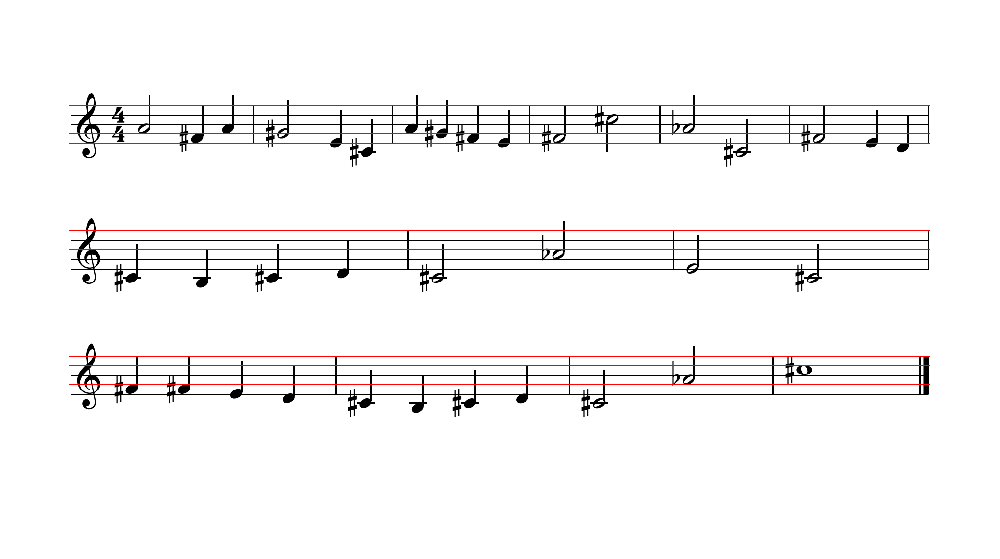

% Read the image
img = imread("Polye.png");

% Convert the image to grayscale
gray_img = rgb2gray(img);

% Threshold the image to create a binary image
bw_img = gray_img < 128;

% Compute the sum of each row of the binary image
row_sums = sum(bw_img,2);

% Find the rows whose sum exceeds a certain value and change their color in the main picture
threshold = 800;
rows_to_change = row_sums > threshold;
rows_to_change1 =find(rows_to_change);


% Define the maximum distance between adjacent elements
max_distance = 2;

% Compute the difference between adjacent elements
d = diff(rows_to_change1);

% Find the indices of the elements that are close to each other
idx = find(abs(d) <= max_distance);

% Remove the elements that are close to each other
rows_to_change1 = setdiff(rows_to_change1,rows_to_change1(idx+1));

R = ones([size(rows_to_change1,1) W])*255;
G = ones([size(rows_to_change1,1) W])*255;
B = ones([size(rows_to_change1,1) W])*255;
Show =ones([size(rows_to_change1,1) W 3]); 
Show(:,:,1) =  R ;
Show(:,:,1) =  G ;
Show(:,:,1) =  B ;

img(rows_to_change1,:,:) = Show;
% Display the resulting image
imshow(img);

finding relative coordinates , create and play music 

Final_D_points;
Final_B_points;

a = zeros([size(Final_sorted_points,1) 1]);
not_id  = zeros([size(Final_sorted_points,1) 1]);
octave  = zeros([size(Final_sorted_points,1) 1]);
dur = round (Final_sorted_points(:,3)) ;
for i=1:size(Final_sorted_points,1)
    if(Final_sorted_points(i,3) == 3.2) % invert half
        a(i) = Mat33(Final_sorted_points(i,1)-h2+19,rows_to_change1);
    else
       a(i) = Mat33(Final_sorted_points(i,1),rows_to_change1);
    end
    if (DBchek(Final_D_points,[Final_sorted_points(i,1) Final_sorted_points(i,2)]))  %Dis
        [not_id(i), octave(i)] = Mat3(a(i),1);        
    elseif (DBchek(Final_B_points,[Final_sorted_points(i,1) Final_sorted_points(i,2)])) %Bem
        [not_id(i)  , octave(i)] = Mat3(a(i),-1);        
    else
        [not_id(i), octave(i)] = Mat3(a(i),0);
    end
end
music = round([not_id,octave,dur]);
fs1 = 4100;
 y = get_music(music, fs1);
sound(y, fs1)
%audiowrite("Polyushka_polye.wav",y,fs1);

## Jane Maryam

clc
clear all
close all

% Read the first image
image1 = imread("Maryam.png");
[H , W ,~] = size(image1); 

% Read the second image
image2 = imread("quarter.PNG");
[h , w ,~] = size(image2);

% Read the third image
image3 = imread("quarter2.PNG");
[h1 , w1 ,~] = size(image3);

% Read the forth image
image4 = imread("halfp.PNG");
[h2 , w2 ,~] = size(image4);

% Read the fifth image
image5 = imread("half2p.PNG");
[h3 , w3 ,~] = size(image5);

% Read the sixth image
image6 = imread("dot.PNG");
[h4 , w4 ,~] = size(image6);



% Convert the images to grayscale
gray_image1 = rgb2gray(image1);
gray_image2 = rgb2gray(image2);
gray_image3 = rgb2gray(image3);
gray_image4 = rgb2gray(image4);
gray_image5 = rgb2gray(image5);
gray_image6 = rgb2gray(image6);



finding  quarters

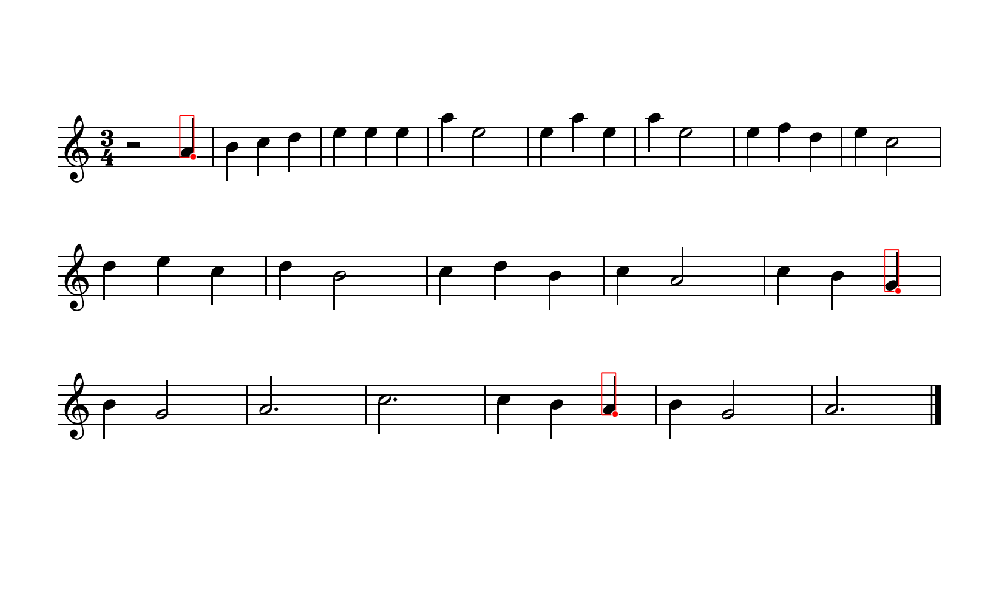

% Find the size of the second image
[height, width] = size(gray_image2);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image2, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.755;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
sorted_points(end,:) = [];
Final_sorted_points = [sorted_points , 4*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  invert quarters

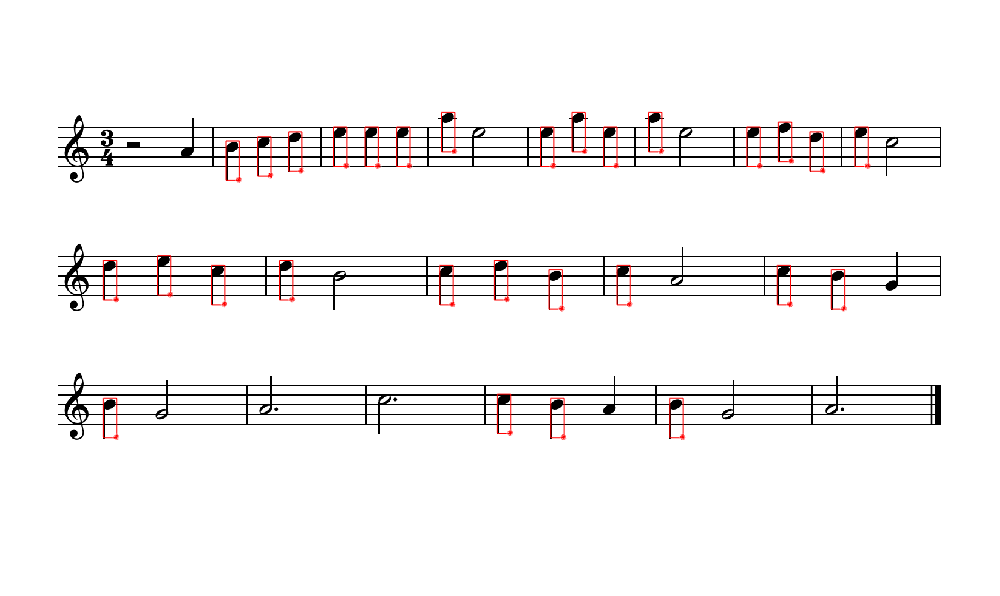

% Find the size of the second image
[height, width] = size(gray_image3);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image3, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.75;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
sorted_points(1,:) = [];
Final_sorted_points = [Final_sorted_points;sorted_points , 4.2*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  halfs

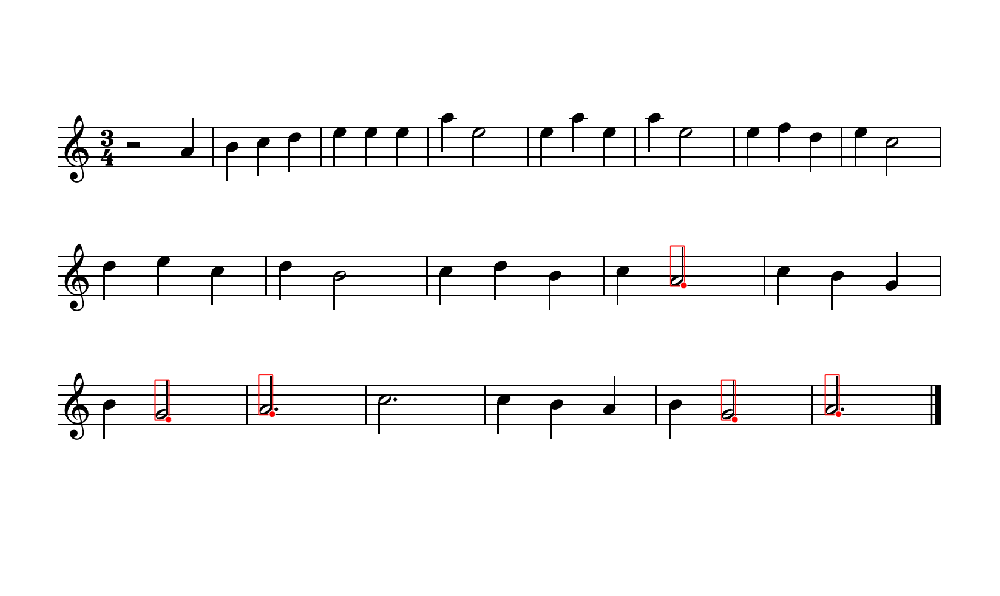

% Find the size of the second image
[height, width] = size(gray_image4);


% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image4, gray_image1);


% Set a threshold for the correlation values to find the matches
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  invert halfs

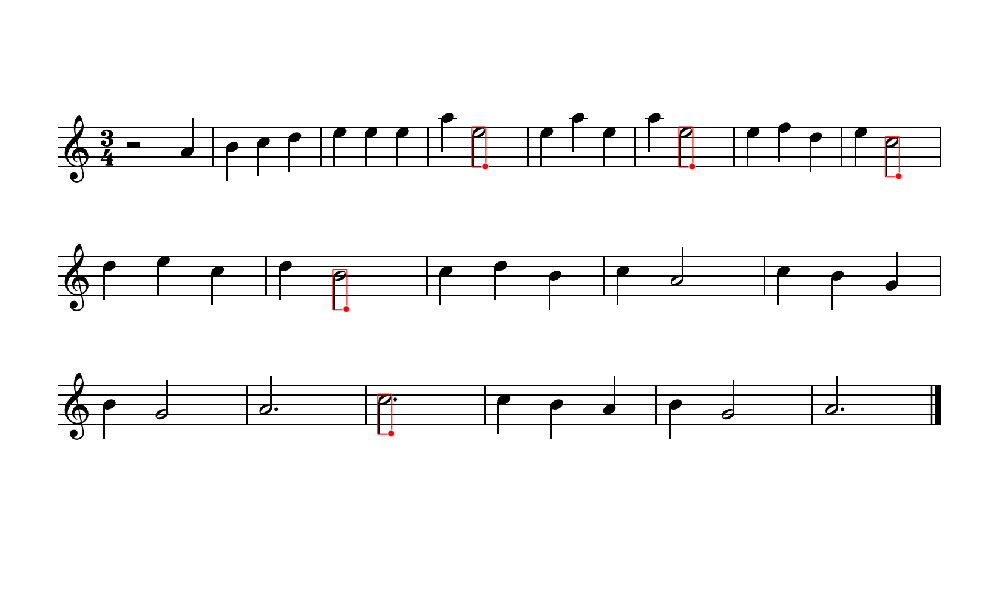

% Find the size of the second image
[height, width] = size(gray_image5);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image5, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.72;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3.2*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

% Divide the vertical axis into three parts
part1 = Final_sorted_points(Final_sorted_points(:,1) <= 190,:);
part2 = Final_sorted_points(Final_sorted_points(:,1) > 190 & Final_sorted_points(:,1) <= 400,:);
part3 = Final_sorted_points(Final_sorted_points(:,1) > 400,:);

% Sort each part based on the horizontal component
part1 = sortrows(part1,2);
part2 = sortrows(part2,2);
part3 = sortrows(part3,2);

% Combine the sorted parts into a single matrix
Final_sorted_points = [part1,; part2; part3];

finding dots

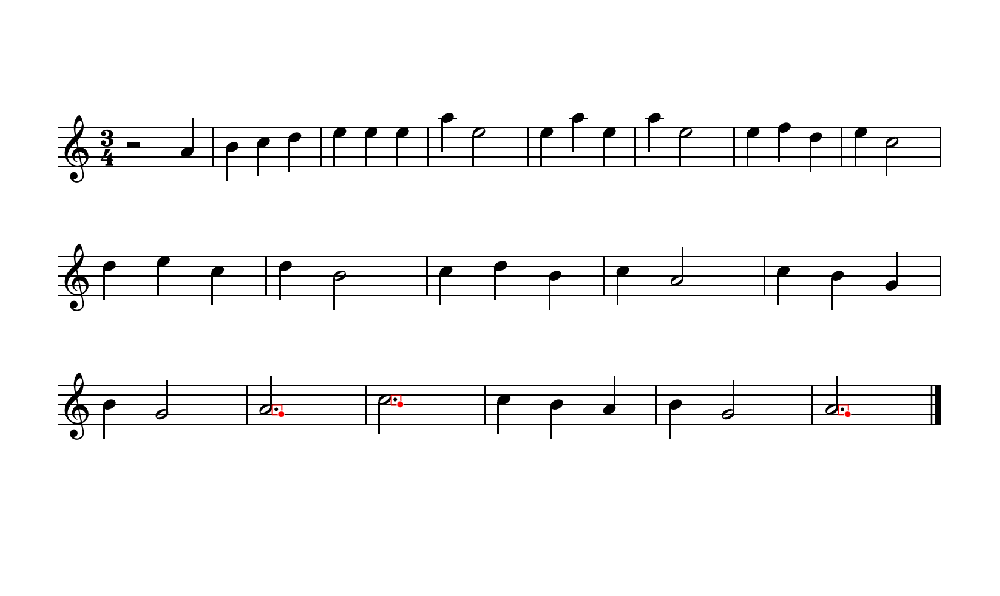

% Find the size of the second image
[height, width] = size(gray_image6);

% Perform template matching using normalized cross-correlation
correlation = normxcorr2(gray_image6, gray_image1);

% Set a threshold for the correlation values to find the matches
threshold = 0.55;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
% Define the minimum distance between points
min_distance = 20;

% Initialize the output matrix
output_points = points(1,:);

% Loop through the input matrix and remove points that are close to each other
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end
% sort
sorted_points = output_points;
Final_dots_points = sorted_points;

rows = sorted_points(:,1);
cols = sorted_points(:,2);
% Show the first image
figure;
imshow(image1);
hold on;
% Draw rectangles around the matches
for i = 1:length(rows)
    top_left_x = cols(i) - w4 + 1;
    top_left_y = rows(i) - h4 + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


% Define the radii of the circles
radii = ones([size(sorted_points,1) 1])*2;

% Draw the circles onto the image
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding carrier lines

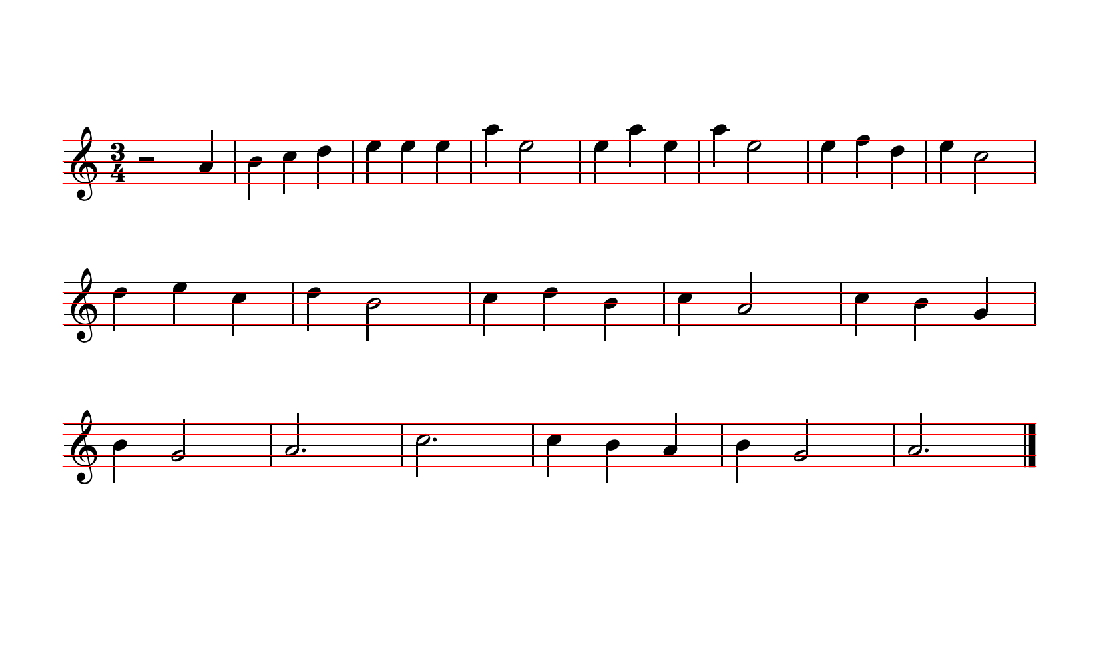

% Read the image
img = imread("Maryam.png");

% Convert the image to grayscale
gray_img = rgb2gray(img);

% Threshold the image to create a binary image
bw_img = gray_img < 128;

% Compute the sum of each row of the binary image
row_sums = sum(bw_img,2);

% Find the rows whose sum exceeds a certain value and change their color in the main picture
threshold = 800;
rows_to_change = row_sums > threshold;
rows_to_change1 =find(rows_to_change);


% Define the maximum distance between adjacent elements
max_distance = 2;

% Compute the difference between adjacent elements
d = diff(rows_to_change1);

% Find the indices of the elements that are close to each other
idx = find(abs(d) <= max_distance);

% Remove the elements that are close to each other
rows_to_change1 = setdiff(rows_to_change1,rows_to_change1(idx+1));

R = ones([size(rows_to_change1,1) W])*255;
G = ones([size(rows_to_change1,1) W])*255;
B = ones([size(rows_to_change1,1) W])*255;
Show =ones([size(rows_to_change1,1) W 3]); 
Show(:,:,1) =  R ;
Show(:,:,1) =  G ;
Show(:,:,1) =  B ;

img(rows_to_change1,:,:) = Show;
% Display the resulting image
imshow(img);

finding relative coordinates , create and play music 

Final_dots_points;

a = zeros([size(Final_sorted_points,1) 1]);
not_id  = zeros([size(Final_sorted_points,1) 1]);
octave  = zeros([size(Final_sorted_points,1) 1]);
dur = round (Final_sorted_points(:,3)) ;
for i=1:size(Final_sorted_points,1)
    if(Final_sorted_points(i,3) == 3.2) % invert half
        a(i) = Mat33(Final_sorted_points(i,1)-h3+16,rows_to_change1);
    elseif (Final_sorted_points(i,3) == 4.2) % invert qurter
        a(i) = Mat33(Final_sorted_points(i,1)-h1+16,rows_to_change1);
    else
       a(i) = Mat33(Final_sorted_points(i,1),rows_to_change1);
    end

    if (Dotcheck(Final_dots_points , [Final_sorted_points(i,1) Final_sorted_points(i,2)])) %Dot check
        dur(i) = 5;
    end
    [not_id(i), octave(i)] = Mat3(a(i),0);
end
music = round([not_id,octave,dur]);
fs1 = 4100;
 y = get_music(music, fs1);
sound(y, fs1)
%audiowrite("Jane_Maryam.wav",y,fs1);

# functions

function TF = DBchek(matrix,coordinate)
    TF = false;
    for i=1:size(matrix,1)
    % Check if any of the distances are less than the threshold value
    
    if (abs(matrix(i,1)-coordinate(1))<80) && (abs(matrix(i,2)-coordinate(2))<40) && coordinate(2)> matrix(i,2)
        TF = true;    
    end   
    end
end

function TF = Dotcheck(matrix,coordinate)
    TF = false;
    for i=1:size(matrix,1)
    % Check if any of the distances are less than the threshold value
    
    if (abs(matrix(i,1)-coordinate(1))<80) && (abs(matrix(i,2)-coordinate(2))<40) && coordinate(2)< matrix(i,2)
        TF = true;    
    end   
    end
end

function a = Mat33(n,M)
% Compute the minimum absolute difference between the matrix and the number
    d = abs(M - n);
    [min_d, row] = min(d);

delta_line = M(2)-M(1);

    R = row; 
    if (row>10)
     R = row - 10;
    elseif(row>5)
     R = row - 5;
    end
     if R ~= 5 & R ~= 1 
        
         if min_d < 5
             a = R + 0.5;
         elseif n > M(row)
             a = R + 1;
         else
             a = R ; 
         end

     elseif  R == 1
         if min_d < 5
             a = 1.5;
         elseif n > M(row)
              a = 2;
         elseif min_d < delta_line+2
              a = 1;  
         elseif min_d < 1.5*delta_line+2
              a = 0.5;  
         elseif min_d < 2*delta_line+2
              a = 0; 
         else
              a = -1;
         end
     elseif  R == 5
         if min_d < 5
             a = 5.5;
         elseif n < M(row)
              a = 5;
         elseif min_d < 0.5*delta_line+2
              a = 6;  
         elseif min_d < 1*delta_line+2
              a = 6.5;  
         elseif min_d < 1.5*delta_line+2
              a = 7;
         elseif min_d < 2*delta_line+2
              a = 7.5;
         elseif min_d < 2.5*delta_line+2
              a = 8;
         elseif min_d < 3*delta_line+2
              a = 8.5;
         else
             a = -1;
         end
     end
      
end

function [not_id, octave] = Mat3 (a, disse_bemol)

switch a
    case 0   % C6
        not_id = (3+disse_bemol);
        octave = 6;        
    case 0.5 % B5        
        not_id = (2+disse_bemol);
        octave = 5;
    case 1   % A5
        not_id = mod(disse_bemol,12);
        octave = 5;     
    case 1.5 % G5
        not_id = (10+disse_bemol);
        octave = 5;        
    case 2   % F5
        not_id = (8+disse_bemol);
        octave = 5;        
    case 2.5 % E5
        not_id = (7+disse_bemol);
        octave = 5;   
    case 3   % D5
        not_id = (5+disse_bemol);
        octave = 5;        
    case 3.5 % C5
        not_id = (3+disse_bemol);
        octave = 5;        
    case 4   % B4
        not_id = (2+disse_bemol);
        octave = 4;
    case 4.5 % A4
        not_id = mod(disse_bemol,12);
        octave = 4;
    case 5   % G4
        not_id = (10+disse_bemol);
        octave = 4;       
    case 5.5 % F4
        not_id = (8+disse_bemol);
        octave = 4;   
    case 6   % E4
        not_id = (7+disse_bemol);
        octave = 4;        
    case 6.5 % D4
        not_id = (5+disse_bemol);
        octave = 4;        
    case 7   % C4
        not_id = (3+disse_bemol);
        octave = 4;
    case 7.5 % B3
        not_id = (2+disse_bemol);
        octave = 3;
    case 8   % A3
        not_id = mod(disse_bemol,12);
        octave = 3;
    case 8.5 % G3 
        not_id = (10+disse_bemol);
        octave = 3;
    otherwise
        not_id = -1;
        octave = -1;  
end
if not_id >= 0
    not_id= not_id +1;
end
end

function z = sin_wave(f, n, fs)
    x = linspace(0, 2*pi, n);
    ring = 30;
    xp = linspace(0, -1*(n*ring/fs), n);
    y = sin(x*f*(n/fs)).*exp(xp);
    z = zeros(n, 2);
    z(:, 1) = y;
    z(:, 2) = y;
end

function y = put_note(note_id, octave, dur, fs)

notes_base = (2.^((0:11)/12))*27.5;
notes_duration = [3200 1600 800 400 1200 100]*0.7;

    if (note_id < 3)
       octave = octave + 1;
    end
    y = sin_wave(notes_base(note_id)*2^octave, round(notes_duration(dur)*(fs/1000)), fs);
end

function m = get_music(music_notes, fs)

    m = [];
    for i = 1:size(music_notes, 1)
        y = put_note(music_notes(i, 1), music_notes(i, 2), music_notes(i, 3), fs);
        m = [m; y];
    end
end